%% ============================
%  CONFIGURACIÓN
% =============================
Fs = 2000;          % Frecuencia de muestreo
win_ms = 100;       % Ventana RMS (ms)
win = round(Fs * win_ms/1000)

win = 200


min_rep_time = 0.5;   % Duración mínima de una repetición (seg)
min_samples = min_rep_time * Fs;

%% ============================
% 1. CARGAR DATOS
% =============================
emg = readtable('C:/Users/dante/OneDrive/Documentos/UDEM/PEF/PEF - IMT 2da prueba/PEF_IMT210.csv');

dataEMG = emg{8:end, 3};    % Ajusta columnas si cambia el archivo

% Quitar filas con NaN
validRows = all(isfinite(dataEMG),2);
dataEMG = dataEMG(validRows,:);

N = size(dataEMG,1);
t = (0:N-1)'/Fs;

%% ============================
% 2. RECTIFICAR Y FILTRAR (ENVOLVENTE)
% =============================
rectified = abs(dataEMG);

% Low-pass para obtener la envolvente EMG
fc_env = 2;
[b,a] = butter(4, fc_env/(Fs/2), 'low');
envelope = filtfilt(b,a,rectified);

%% ============================
% 3. RMS MÓVIL
% =============================
RMS = zeros(size(rectified));
for ch = 1:size(rectified,2)
    RMS(:,ch) = sqrt(movmean(rectified(:,ch).^2, win));
end

%% ============================
% 4. DETECCIÓN DE REPETICIONES
% =============================
% Usamos la suma del envelope de todos los músculos como señal "global"
global_signal = sum(envelope,2);

% Umbral adaptativo: 30% sobre la media del reposo detectado automáticamente
baseline = median(global_signal(1:Fs)); % primeros 1s ≈ reposo
threshold = baseline + 0.3 * std(global_signal);

is_active = global_signal > threshold;

% Agrupar muestras activas en "bloques" = repeticiones
rep_starts = [];
rep_ends = [];

inside = false;

for i = 2:N
    if ~inside && is_active(i) == 1
        inside = true;
        rep_starts(end+1) = i;
    elseif inside && is_active(i) == 0
        inside = false;
        rep_ends(end+1) = i;
    end
end

% Ajustar si termina activo
if inside
    rep_ends(end+1) = N;
end

%% Filtrar repeticiones demasiado cortas
valid_idx = (rep_ends - rep_starts) > min_samples;
rep_starts = rep_starts(valid_idx);
rep_ends = rep_ends(valid_idx);

num_reps = length(rep_starts);

fprintf("Se detectaron %d repeticiones.\n", num_reps);

Se detectaron 20 repeticiones.



%% ============================
% 5. CALCULAR RMS PROMEDIO POR REPETICIÓN
% =============================
RMS_per_rep = zeros(num_reps, size(RMS,2));

for k = 1:num_reps
    idx = rep_starts(k):rep_ends(k);
    RMS_per_rep(k,:) = mean(RMS(idx,:), 1);
end

%Filtrar outliars the RMS_per_rep
%Filtrar outliers en RMS_per_rep utilizando el método de 1.5 IQR
% Q1 = quantile(RMS_per_rep, 0.25);
% Q3 = quantile(RMS_per_rep, 0.75);
% IQR = Q3 - Q1;
% outlier_idx = any(RMS_per_rep < (Q1 - 1.5 * IQR) | RMS_per_rep > (Q3 + 1.5 * IQR), 2);
% RMS_per_rep(outlier_idx, :) = [];
% num_reps = size(RMS_per_rep, 1) % Actualizar el número de repeticiones después de filtrar

% Promedio global de las repeticiones
RMS_global = mean(RMS_per_rep,1);

disp("RMS promedio por repetición (canales en columnas):");

RMS promedio por repetición (canales en columnas):


disp(RMS_per_rep);

   1.0e-04 *

    0.3539
    0.3429
    0.3385
    0.3297
    0.3029
    0.3529
    0.3079
    0.3601
    0.3553
    0.3880
    0.3093
    0.3444
    0.3370
    0.4321
    0.3715
    0.3866
    0.4691
    0.3316
    0.3393
    0.3650




disp("RMS promedio global de las 20 repeticiones:");

RMS promedio global de las 20 repeticiones:


disp(RMS_global);

   3.5590e-05



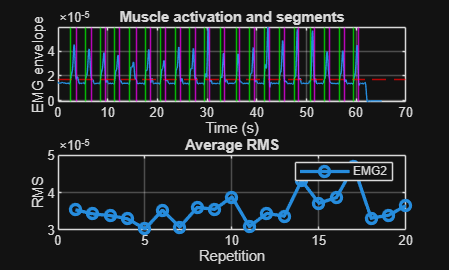


%% ============================
% 6. GRAFICAR SEGMENTACIÓN Y RESULTADOS
% =============================

figure;
subplot(2,1,1);
plot(t, global_signal); hold on;
yline(threshold, '--r');
title("Muscle activation and segments");
xlabel("Time (s)");
ylabel("EMG envelope");
grid on;

for k = 1:num_reps
    xline(t(rep_starts(k)), 'g');
    xline(t(rep_ends(k)), 'm');
end

% subplot(3,1,2);
% plot(t, RMS);
% title("RMS per Channel");
% xlabel("Time (s)");
% ylabel("RMS");
% grid on;

subplot(2,1,2);
plot(RMS_per_rep, 'o-','LineWidth',2);
title("Average RMS");
xlabel("Repetition");
ylabel("RMS");
legend("EMG2");
grid on;